clear
clc
% ---------- Kommentarer ----------
% Den lösningen kan skrivas om i generell form, vi får då systemet:
% [x_k, x_k+1] = [0, 1; -0.5, 2.25]*[x_k-1, x_k]
% D.v.s. x_k = A*x_k-1
% Vi studerar A för att förstå hur stabilt/robust/känsligt systemet är
A = [0, 1; -0.5, 2.25]

A =          0    1.0000
   -0.5000    2.2500


lambdas = eig(A) 

lambdas =     0.2500
    2.0000


conditionA = cond(A) % Vi ser att conditionstalet är "relativt" högt och kan ge problem vid iterativa beräkningar

conditionA = 12.5453

log10(cond(A)) %  > 1 , d.v.s.  vi kommer att förlora decimal-noggrannhet i lösningen

ans = 1.0985


% Från detta får vi två punkter:
% 1. Från Heath 2.3.4 Error Bound har vi: att vi förlorar 1 decimals
% noggrannhet relativt noggrannheten hos indata (vilket är esp_machine).
% Och detta leder till cancellation. 
%
% 2. Från punkt 1. så kommer felet att växa eftersom lösningen till
% systemet är också indata till systemet i nästa iteration. Då är
% lösningen x_k indata x_k-1 för nästa iteration. Felet/error/problemet
% växer då för varje iteration.

## Teoretisk lösning

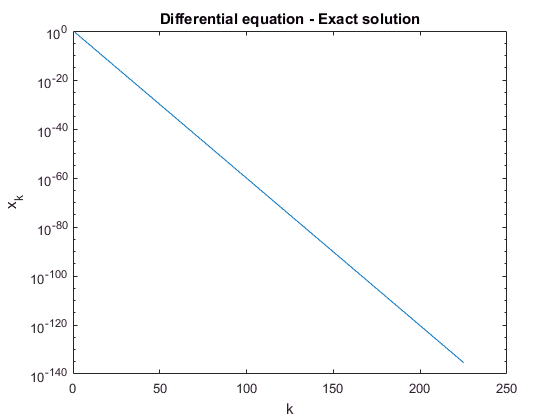

k = 1:225;

xTrueSingle = 4.^(1-k)./3;
n = 1:60;
xTrueDouble = 4.^(1-n)./3;
semilogy(xTrueSingle);
title('Differential equation - Exact solution')
ylabel('x_k')
xlabel('k')

## Double precision

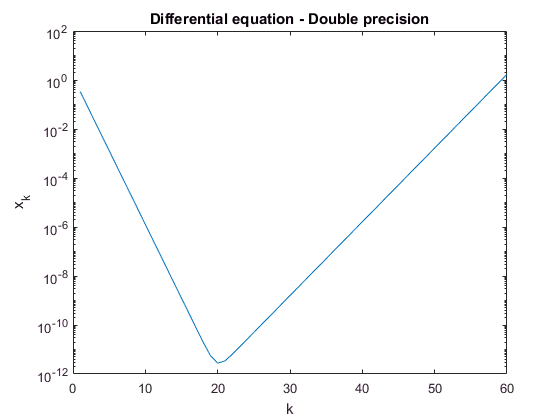

x1 = 1/3;
x2 = 1/12;

n = 60; % double
serie = zeros(n,1);
serie(1) = x1;
serie(2) = x2;
for k = 2:(n-1)
    xk = difference_eq_17(serie(k), serie(k-1));
    serie(k+1) = xk;
end

figure
semilogy(serie);
title('Differential equation - Double precision')
ylabel('x_k')
xlabel('k')

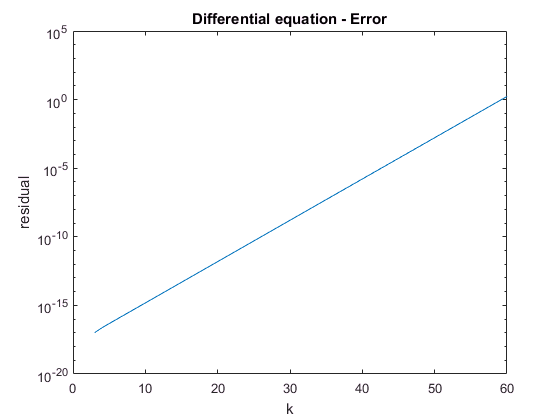


% Feluppskattning L1
figure
residual = abs(xTrueDouble' - serie);
semilogy(residual);
title('Differential equation - Error')
ylabel('residual')
xlabel('k')

## Single precision

Monotont avtagande hela tiden

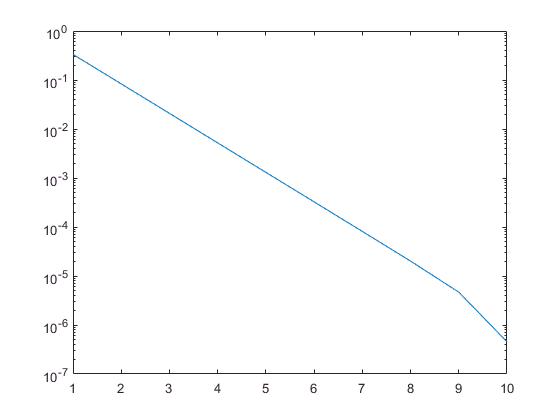

x1 = single(1/3);   
x2 = single(1/12);

n = 225; % single
serie = single(zeros(n,1));
serie(1) = x1;
serie(2) = x2;
for k = 2:(n-1)
    xk = single(difference_eq_17(single(serie(k)), single(serie(k-1))));
    serie(k+1) = xk;
end

semilogy(serie); % Visar ej negativa värden

semilogy(abs(serie));

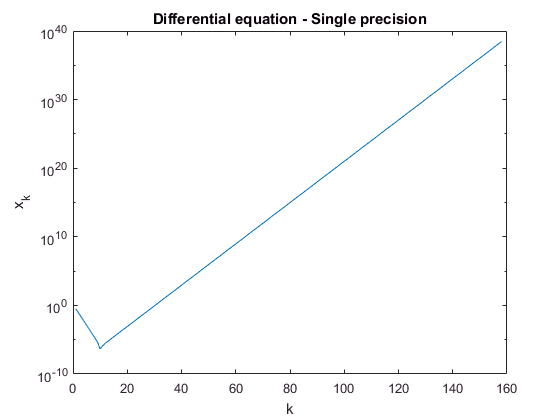

% plot(serie);
title('Differential equation - Single precision')
ylabel('x_k')
xlabel('k')

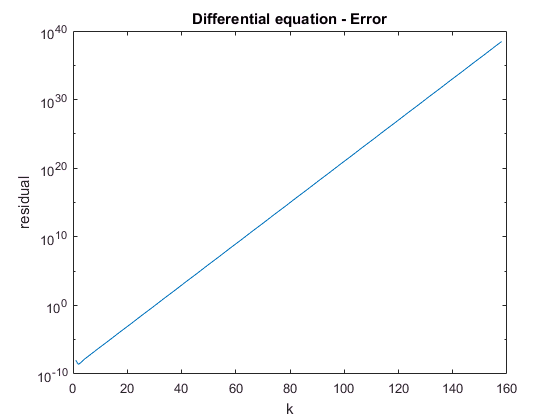


% Feluppskattning L1
figure
residual = abs(xTrueSingle' - serie);
semilogy(residual);
title('Differential equation - Error')
ylabel('residual')
xlabel('k')